%%%%%%%%%%%%%%%%% 1. Prepare data for analysis %%%%%%%%%%%%
% read in data
D1 = readtimetable("GDPC1.csv") ;
D2 = readtimetable("FEDFUNDS.csv") ;
D3 = readtimetable("GDPDEF.csv") ;


% Aggregate D2 to quarterly
D2 = retime(D2,"quarterly","mean") ;


% Create annualized log growth rates for D1
D1_lag = lag(D1);
D1 = synchronize(D1, D1_lag);
D1.growth_c1 = 4 .* (log(D1.GDPC1_D1) - log(D1.GDPC1_D1_lag));
D1.GDPC1_D1 = [];
D1.GDPC1_D1_lag = [];

% Create annualized log growth rates for D3
D3_lag = lag(D3);
D3 = synchronize(D3, D3_lag);
D3.growth_def = 4 .* (log(D3.GDPDEF_D3) - log(D3.GDPDEF_D3_lag));
D3.GDPDEF_D3 = [];
D3.GDPDEF_D3_lag = [];

% Combine tables
Data = synchronize(D1,D2,D3);
Data(1, :) = [] ;
Data.diff = Data.FEDFUNDS - Data.growth_def ;
Data.FEDFUNDS = [] ;
Data

Data = 262×3 timetable
       DATE       growth_c1     growth_def     diff  
    __________    __________    __________    _______

    1954-07-01      0.044934    0.0053078      1.0247
    1954-10-01      0.077522     0.010888     0.97578
    1955-01-01       0.11266     0.018764      1.3246
    1955-04-01      0.064578     0.016347      1.4837
    1955-07-01      0.053671     0.027869      1.9121
    1955-10-01      0.023955     0.039438      2.3172
    1956-01-01     -0.015552     0.039903      2.4434
    1956-04-01      0.032927      0.02347      2.6699
    1956-07-01    -0.0035897     0.049875      2.7601
    1956-10-01      0.065301     0.016118      2.9105
    1957-01-01


% Put Data into matrix
matdata = [Data.growth_c1,Data.growth_def, Data.diff];
matdata_flip = flip(matdata);
matdata_flipinv = matdata_flip.';
matdata_long = matdata_flipinv(:);

%%%%%%%%%%%%%%%% 2. Problem 4 (i) %%%%%%%%%%%%%%%%%%%%%%

% Create X (13 x 258). Each column corresponds to x_t (n x 1)
% for t = (p+1)...T
X = zeros(13,258);
X(1,:) = 1;
for j = 1:258
    X(2:13,j) = matdata_long((778-3*j):(789-3*j));
end
X = X.';
y = matdata(5:end,:);

% Run OLS to get beta_hat
    
beta_hat = (y.'*X)/(X.'* X) ;

% Use canned package to check my work:
Mdl = varm(3,4) ;
Estmdl = estimate(Mdl,matdata) ;
summarize(Estmdl) ;

 
   AR-Stationary 3-Dimensional VAR(4) Model
 
    Effective Sample Size: 258
    Number of Estimated Parameters: 39
    LogLikelihood: 1091.44
    AIC: -2104.89
    BIC: -1966.32
 
              Value       StandardError    TStatistic      PValue  
           ___________    _____________    __________    __________

    Co…       0.018271      0.0049637         3.6809     0.00023237
    Co…     0.00063304       0.001615        0.39198        0.69508
    Co…       -0.31123        0.12146        -2.5624       0.010395
    AR…        0.26671       0.063368         4.2089     2.5667e-05
    AR…       0.016187       0.020617        0.78511        0.43239
    AR…         6.8703         1.5506         4.4308     9.3901e-06
    AR…</

gctest(Estmdl) ;

                    H0                         Decision         Distribution    Statistic      PValue      CriticalValue
    __________________________________    __________________    ____________    _________    __________    _____________

    "Exclude lagged Y2 in Y1 equation"    "Cannot reject H0"     "Chi2(4)"       6.2971         0.17803       9.4877    
    "Exclude lagged Y3 in Y1 equation"    "Reject H0"            "Chi2(4)"       28.958      7.9742e-06       9.4877    
    "Exclude lagged Y1 in Y2 equation"    "Cannot reject H0"     "Chi2(4)"       6.0537         0.19518       9.4877    
    "Exclude lagged Y3 in Y2 equation"    "Reject H0"            "Chi2(4)"       18.513      0.00097916       9.4877    
    "Exclude lagged Y1 in Y3 equation"    "Reject H0"            "Chi


% Calculate sigma_hat
u_hat = y - X*beta_hat.' ;
sigma_hat = (1/258).*(u_hat.'*u_hat) ;

% Calculate S_hat
S_hat = (1/258).*(X.'*X) ;

% Calculate Omega_hat
Omega_hat = kron(inv(S_hat),sigma_hat);

% Calculate W_hat - Wald statistic
vecbeta_hat = beta_hat(:) ;

R = zeros(4,39) ;
R(1,7) = 1;
R(2,16) = 1;
R(3,25) = 1;
R(4,34) = 1;

b = zeros(4,1) ;

W_hat = (258).*(R*vecbeta_hat - b).'*inv(R*Omega_hat*R.')*(R*vecbeta_hat-b) ;

% Calculate p-value
p = 1 - chi2cdf(W_hat,4) 

p = 0.1567


%%%%%%%%%%%%%%%% 3. Problem 4 (ii) %%%%%%%%%%%%%%%%%%%%%


% Collect AIC and BIC criteria for models with p <= 20 lags
IC = zeros(20,2) ;
model_collection = varm.empty ;
for p = 1:20
    model_collection(p) = varm(3,p) ;
    IC(p,1) = estimate(model_collection(p),matdata(21-p:end,:)).summarize.AIC ;
    IC(p,2) = estimate(model_collection(p),matdata(21-p:end,:)).summarize.BIC ;
end
model_collection ;
IC ;


% index reports the selected lag numbers for AIC and BIC, respectively
[low,index] = max(-IC) 

low = 1.0e+03 *

    2.0375    1.9090


index =     11     1


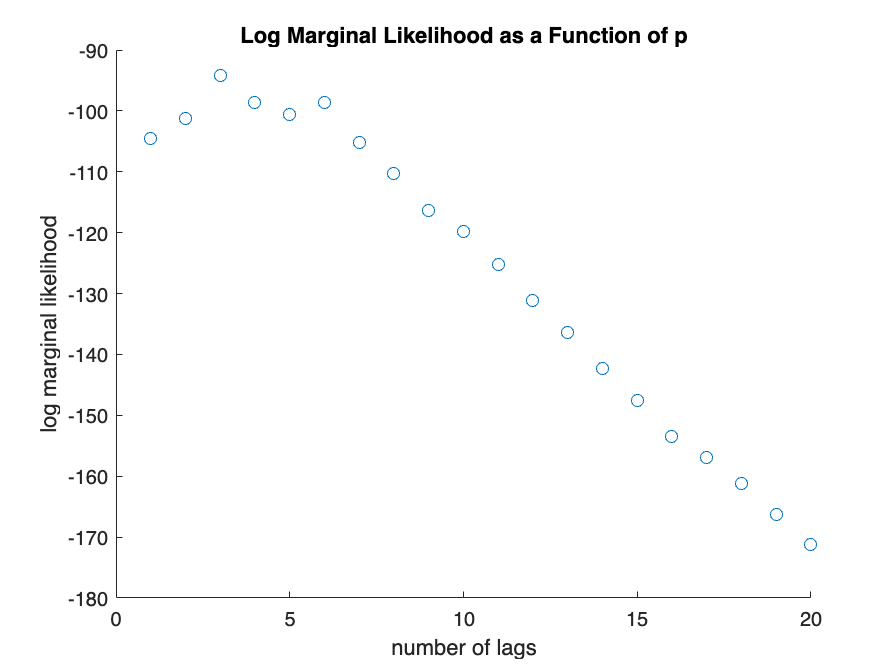

%%%%%%%%%%%%%%% 4. Problem 5 (i) %%%%%%%%%%%%%%%%%%%%%%%
ml_vec = zeros(20,1) ;
for p = 1:20
    ml_vec(p,:) = glp(p,matdata_long, matdata) ;
end


[highml,indexml] = max(ml_vec) ;

scatter(1:20,log(ml_vec))
xlabel('number of lags')
ylabel('log marginal likelihood')
title('Log Marginal Likelihood as a Function of p')

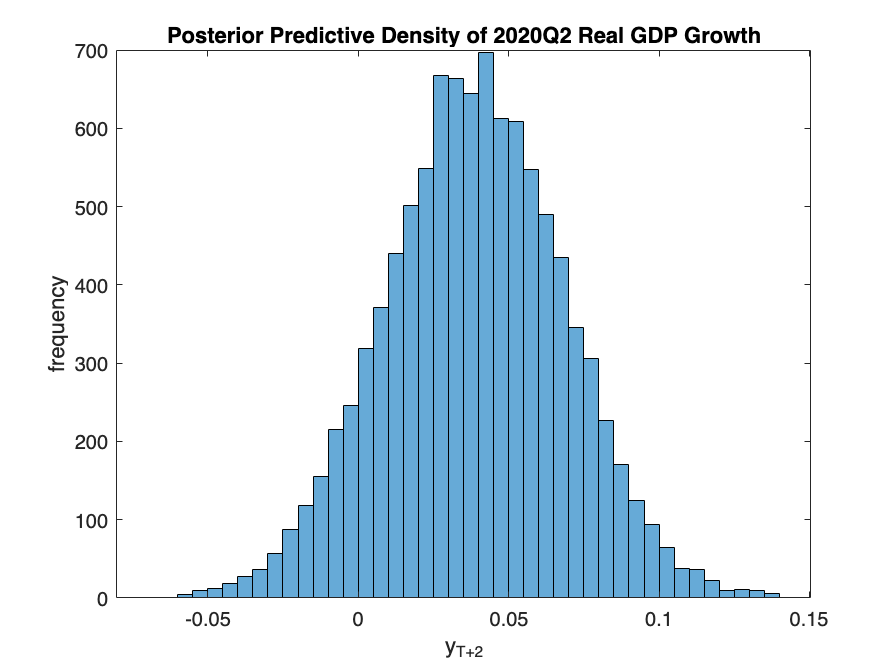

%%%%%%%%%%%%%%% 5. Problem 5 (ii) %%%%%%%%%%%%%%%%%%%%

% We choose p = 3 from above
[ml_star, Psi_star, eps_hat_star, B_hat_star, Omega_star, x_star] = glp(3,matdata_long,matdata) ;

% Create hyperparameters for IW and N prior distributions
IW_mean = Psi_star + eps_hat_star.'*eps_hat_star + B_hat_star.'*inv(Omega_star)*B_hat_star ;
IW_df = 242+5 ;
N_mean = B_hat_star(:) ;
N_var_part2 = inv(x_star.'*x_star + inv(Omega_star)) ;

% Simulate y_{1,T+2} given beta_draw, Sigma_draw
x_t263 = zeros(10,1) ;
x_t263(1) = 1 ;
x_t263(2:10) = matdata_long(1:9) ;

y_posterior = zeros(10000,1) ;

for r = 1:10000
    [beta_draw, Sigma_draw] = draw(IW_mean,IW_df, N_mean, N_var_part2) ;
    u_t263 = mvnrnd(zeros(3,1),Sigma_draw) ;
    u_t263 = u_t263.' ;
    B_draw = zeros(10,3);
    B_draw(:,1) = beta_draw(1:10);
    B_draw(:,2) = beta_draw(11:20);
    B_draw(:,3) = beta_draw(21:30);
    B_draw_transpose = B_draw.' ;
    y_t263 = B_draw_transpose*x_t263 + u_t263 ;

    x_t264 = zeros(10,1) ;
    x_t264(1) = 1 ;
    x_t264(2:4) = y_t263(1:3) ;
    x_t264(5:10) = matdata_long(1:6) ;
    u_t264 = mvnrnd(zeros(3,1),Sigma_draw) ;
    u_t264 = u_t264.' ;
    y_t264 = B_draw_transpose*x_t264 + u_t264 ;
    y_posterior(r) = y_t264(1) ;
end


histogram(y_posterior)
title('Posterior Predictive Density of 2020Q2 Real GDP Growth')
xlabel('y_{T+2}')
ylabel('frequency')

function [beta, Sigma] = draw(IW_mean, IW_df, N_mean, N_var_part2)
    Sigma = iwishrnd(IW_mean,IW_df) ;
    beta = mvnrnd(N_mean,kron(Sigma,N_var_part2)) ;
    beta = beta.' ;
end


% Function that computes posterior elements given lag number p
function [ml, Psi, eps_hat, B_hat, Omega, x] = glp(p,matdata_long, matdata)
    k = 1 + 3*p ;
    X = zeros(k,242);
    X(1,:) = 1;
    for j = 1:242
        X(2:end,j) = matdata_long(787-3*(20+j-1):789-3*(20+j-p));
    end
    x = X.' ;
    y = matdata(21:end,:) ;
  
        
        % Create Omega %
    Omega = zeros(k,k) ;
    if p == 0
        Omega(1,1) = 100 ;
    else
        Omega(1,1) = 100 ;
        for l = 2:k
            Omega(l,l) = 100 / ((ceil((l-1)/3))^2) ;
        end
    end

    Psi = [.0004 0 0; 0 .0004 0; 0 0 .0004] ;

    B_hat = (x.'*x + inv(Omega))\(x.'*y) ;
    eps_hat = y - x*B_hat ;

        % Create 6 scalars to be multiplied together for final likelihood
    %s1 = (1/pi)^(3*242/2) ;
    %s2 = gamma3((242+5)/2)/gamma3(5/2) ;
    s3 = det(Omega)^(-3/2) ;
    s4 = det(Psi)^(5/2) ;
    s5 = det(x.'*x + inv(Omega))^(-3/2) ;
    s6 = det(Psi + eps_hat.'*eps_hat + B_hat.'*inv(Omega)*B_hat)^(-(242 + 5)/2) ;

    ml = s3*s4*s5*s6 ;
end

% function result = gamma3(a)
%     result = (pi^(3/2))*gamma(a)*gamma(a-.5)*gamma(a-1);
% end






















